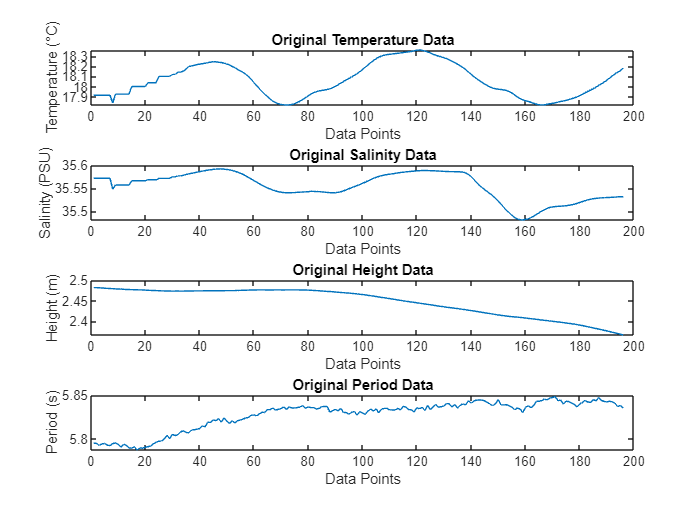

clc;
close all;
clear;
% Read the Excel file (assuming file is named MarineData.xlsx)
dataTable = readtable("wave.xlsx");

% Extract Temperature, Salinity, Height, and Period from rows 3 to 200
temperature = dataTable.sea_temperature(3:200);
salinity = dataTable.sea_salinity(3:200);
height = dataTable.wave_height(3:200);
period = dataTable.wave_period(3:200);
m = 1:numel(temperature);

% Plot original data
figure;
subplot(4, 1, 1);
plot(m, temperature);
xlabel('Data Points');
ylabel('Temperature (°C)');
title('Original Temperature Data');

subplot(4, 1, 2);
plot(m, salinity);
xlabel('Data Points');
ylabel('Salinity (PSU)');
title('Original Salinity Data');

subplot(4, 1, 3);
plot(m, height);
xlabel('Data Points');
ylabel('Height (m)');
title('Original Height Data');

subplot(4, 1, 4);
plot(m, period);
xlabel('Data Points');
ylabel('Period (s)');
title('Original Period Data');

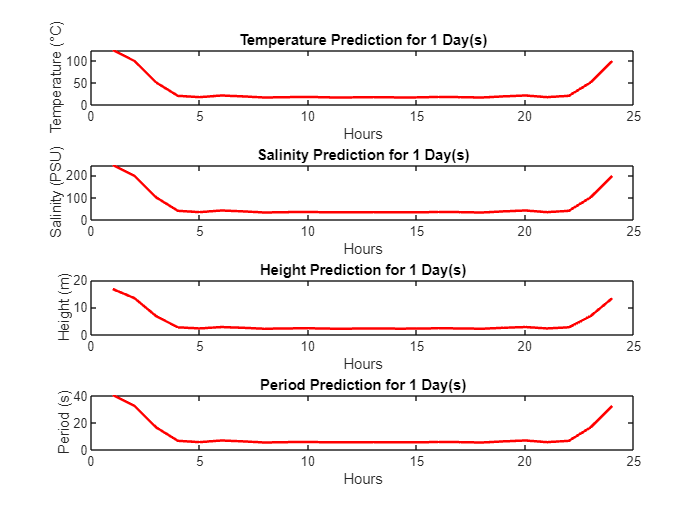

Average output for 1 Day(s):
    Avg_Temperature    Avg_Salinity    Avg_Height    Avg_Period
    _______________    ____________    __________    __________

        32.342            64.271         4.3547        10.574  



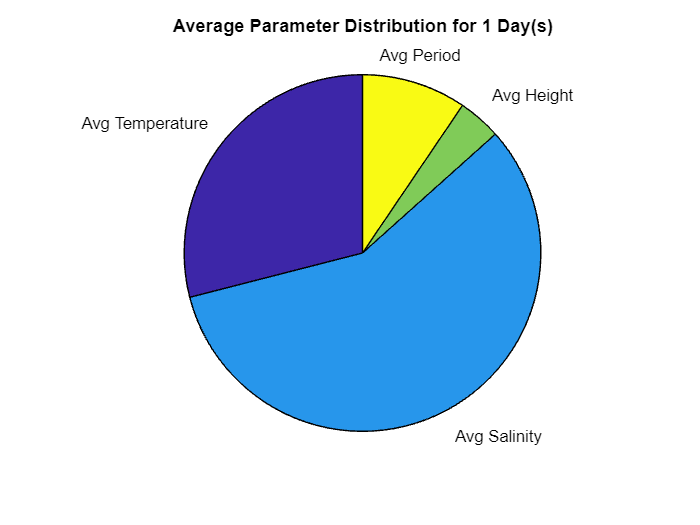

         Parameter         Percentage
    ___________________    __________

    {'Avg Temperature'}      28.995  
    {'Avg Salinity'   }      57.621  
    {'Avg Height'     }      3.9041  
    {'Avg Period'     }      9.4798  



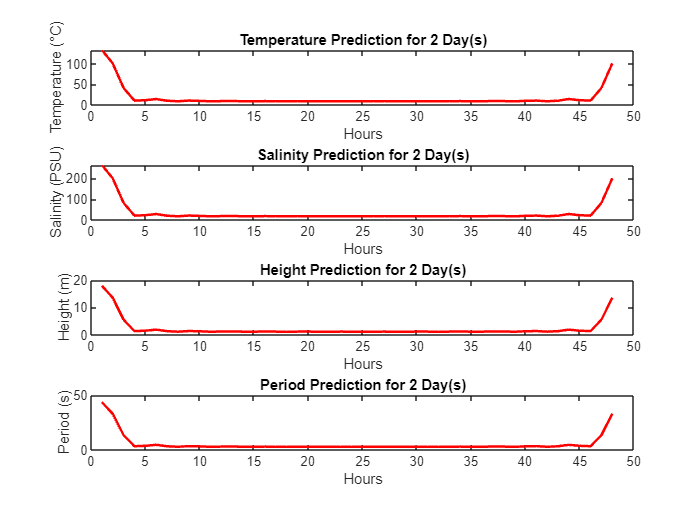

Average output for 2 Day(s):
    Avg_Temperature    Avg_Salinity    Avg_Height    Avg_Period
    _______________    ____________    __________    __________

         19.97            39.695         2.6885        6.5312  



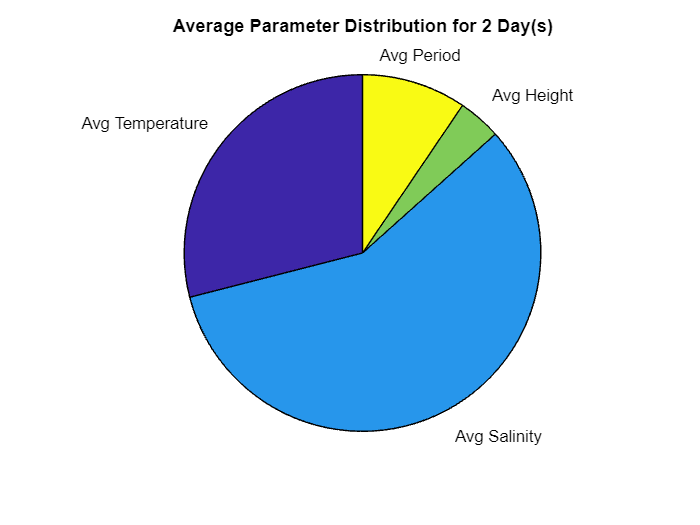

         Parameter         Percentage
    ___________________    __________

    {'Avg Temperature'}       28.99  
    {'Avg Salinity'   }      57.626  
    {'Avg Height'     }      3.9029  
    {'Avg Period'     }      9.4813  




% Define window size
window_size = 25;

% Process each windowed segment of the data
for start_idx = 1:window_size:length(temperature) - window_size
    % Extract segments based on the window size
    temp_segment = temperature(start_idx:start_idx + window_size - 1);
    salinity_segment = salinity(start_idx:start_idx + window_size - 1);
    height_segment = height(start_idx:start_idx + window_size - 1);
    period_segment = period(start_idx:start_idx + window_size - 1);
    
    % Apply FFT to each segment
    temp_fft = fft(temp_segment);
    salinity_fft = fft(salinity_segment);
    height_fft = fft(height_segment);
    period_fft = fft(period_segment);

end

% Call function for 24-hour predictions for 1 and 2 days
prediction_days = [1,2];  % Days for prediction
for i = 1:length(prediction_days)
    makePrediction(temp_fft, salinity_fft, height_fft, period_fft, prediction_days(i));
end


% Function for prediction


function makePrediction(temperature_fft, salinity_fft, height_fft, period_fft, days)
    % Generate new time points for prediction (24 hours per day)
    predicted_hours = linspace(1, 24 * days, 24 * days);
    predicted_hours_rad = (2 * pi * predicted_hours) / (24 * days);

    % Interpolate FFT data
    interpolated_temperature = interp1(1:numel(temperature_fft), temperature_fft, predicted_hours_rad, 'linear', 'extrap');
    interpolated_salinity = interp1(1:numel(salinity_fft), salinity_fft, predicted_hours_rad, 'linear', 'extrap');
    interpolated_height = interp1(1:numel(height_fft), height_fft, predicted_hours_rad, 'linear', 'extrap');
    interpolated_period = interp1(1:numel(period_fft), period_fft, predicted_hours_rad, 'linear', 'extrap');

    % Inverse Fourier transform to get predicted values
    predicted_temperature = real(ifft(interpolated_temperature));
    predicted_salinity = real(ifft(interpolated_salinity));
    predicted_height = real(ifft(interpolated_height));
    predicted_period = real(ifft(interpolated_period));

    % Plot the predictions
    figure;
    
    subplot(4, 1, 1);
    plot(predicted_hours, predicted_temperature, 'r', 'LineWidth', 1.5);
    xlabel('Hours');
    ylabel('Temperature (°C)');
    title(['Temperature Prediction for ', num2str(days), ' Day(s)']);
    

    subplot(4, 1, 2);
    plot(predicted_hours, predicted_salinity, 'r', 'LineWidth', 1.5);
    xlabel('Hours');
    ylabel('Salinity (PSU)');
    title(['Salinity Prediction for ', num2str(days), ' Day(s)']);
   

    subplot(4, 1, 3);
    plot(predicted_hours, predicted_height, 'r', 'LineWidth', 1.5);
    xlabel('Hours');
    ylabel('Height (m)');
    title(['Height Prediction for ', num2str(days), ' Day(s)']);
  

    subplot(4, 1, 4);
    plot(predicted_hours, predicted_period, 'r', 'LineWidth', 1.5);
    xlabel('Hours');
    ylabel('Period (s)');
    title(['Period Prediction for ', num2str(days), ' Day(s)']);
    

    % Calculate average values for each day
    avg_temperature = mean(predicted_temperature(1:24));
    avg_salinity = mean(predicted_salinity(1:24));
    avg_height = mean(predicted_height(1:24));
    avg_period = mean(predicted_period(1:24));

    % Display the average table for each day
    avg_table = table(avg_temperature, avg_salinity, avg_height, avg_period, 'VariableNames', {'Avg_Temperature', 'Avg_Salinity', 'Avg_Height', 'Avg_Period'});
    disp(['Average output for ', num2str(days), ' Day(s):']);
    disp(avg_table);
    
    % Create a pie chart for average values
    avg_values = [avg_temperature, avg_salinity, avg_height, avg_period];
    labels = {'Avg Temperature', 'Avg Salinity', 'Avg Height', 'Avg Period'};
    
    % Calculate percentages for pie chart
    total_avg = sum(avg_values);
    percentages = (avg_values / total_avg) * 100;

    % Plot the pie chart
    figure;
    pie(percentages, labels);
    title(['Average Parameter Distribution for ', num2str(days), ' Day(s)']);
   
    % Display percentages in the figure
    percentage_table = table(labels', percentages', 'VariableNames', {'Parameter', 'Percentage'});
    disp(percentage_table);
   
    
end
